clc;
clear all;
fontsize = 14;
addpath("../utils")

This script showcases the genStrlkStream function, to generate multiple Starlink frames. In this playground, you can view a spectrogram, a power plot (PSD or Power vs time), a cross correlation with a local replica, a CAF against the local replica, and a histogram of the samples from the CAF.

%--------------------------------------%
%----------------Option----------------%
%--------------------------------------%
perform_acq = 1;

pwrPlot_en = 1;
specPlot_en = 1;
% Require perform_acq
    aqPlot_en = 1;
    hist_en = 1; % works when frame is exactly at center with no frame before it
    crossCorr_en = 1;

filter_en = 1; % Should probably always filter
Filter_factor = 0.85; % Between 0 and 1

Specifying the falce alarm Pfcell, doppler the signal should have Fd_hard, the length in time of the capture Tfull, a vecotr of 1s and 0s indicating the presence of frames, and the receiver sampling rate and center.

%--------------------------------------%
%----------------Params----------------%
%--------------------------------------%
NFFT = 2^10; % # of FFT points for spectrogram, if too many points, it is reduced later
Fs = 240e6; % Starlink full BW
Pfcell = 1e-8;
Fd_hard = -128870.00;
Tfull = 15*1/750;        % Interval of data to load (sec)
present = [1,0,0,1,0,1];% only for simulation
Fsr = 62500000;
Fcr = 1.1830e+10;

%--------------------------------------%
%---------Signal Input params----------%
%--------------------------------------%
% Signal to noise ratio, in dB
s.SNRdB = -5;
% Receiver sample rate.  If this is less than Fs, then the signal is filtered
% before resampling to prevent aliasing.  Set Fsr to Fs to skip resampling.
s.Fsr = Fsr;
% Receiver center frequency, in Hz
s.Fcr = Fcr;
% Simulated doppler
s.beta = -Fd_hard./getClosestFch(s.Fcr); 
s.tau = 1/750/2;
s.Tdur = Tfull - s.tau;
s.present = present;

%--------------------------------------%
%-----------Read Input File -----------%
%--------------------------------------%
[y,~] = genStrlkStream(s);
    
if (filter_en)
    y = lowpass(y,Filter_factor.*Fsr/2,Fsr);
    ratio = Filter_factor.*Fsr./Fs;
else
    ratio = 1;
end

To acquire the signal, some parameters are necessary to specify the search grid.

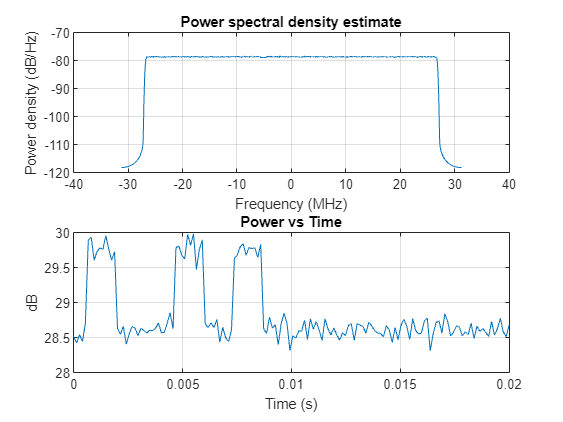

%--------------------------------------%
%---------Acquisition Params-----------%
%--------------------------------------%
fmax = 300e3;
fstep = 5e3; 
fmin = -300e3;

fstepFine = 10;
Pfa = 0.1;

%--------------------------------------%
%--------- Perform Acquisition---------%
%--------------------------------------%
if (perform_acq)
    a.Fsr = Fsr;
    a.Fcr = Fcr;
    a.fmax = fmax;
    a.fstep = fstep;
    a.fstepFine = fstepFine;
    a.fmin = fmin;
    Nk = floor(Fsr.*1/750);
    a.y = y(1:Nk);
    a.Pfa = Pfa;
    out = fftAcqStrlk(a);
end

%--------------------------------------%
%--------------Plotting ---------------%
%--------------------------------------%

% -- Pwr plots
if (pwrPlot_en)
    figure(1);clf
    plotPwr(y,round(Tfull./(1/750)*10),0,length(y)/Fsr,Fsr,NFFT)
end

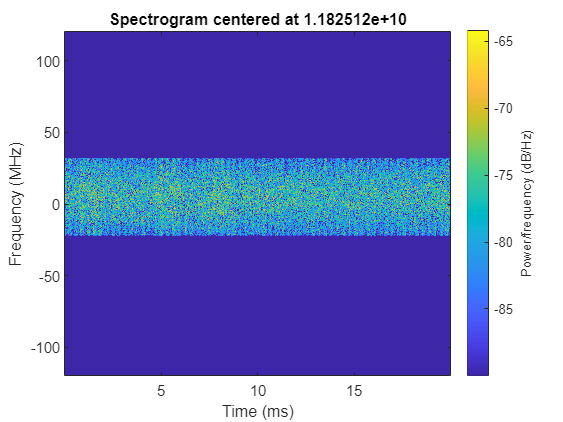


% -- Spectrogram
if(specPlot_en)
    figure(2);clf
    F = Fs/1024;
    chIdx = round((Fcr/1e9 - 10.7 - F/2/1e9)/0.25 + 0.5);
    Fcii = (10.7e9 + F/2 + 250e6*(chIdx - 0.5));
    plotSpec(y,0,0,Fcr,Fsr,Fcii,Fs,NFFT)
end


% -- Acquisition
if (perform_acq)
    fprintf("    Fdop     |     tau    | \n")
    fprintf("----------------------------\n")
    fprintf("   %+10.2f |  %+6.2e | \n", out.fdfine, out.tau)
end

    Fdop     |     tau    | 


----------------------------


   -122300.00 |  +6.67e-04 | 


SNR estimate : -5.43 dB


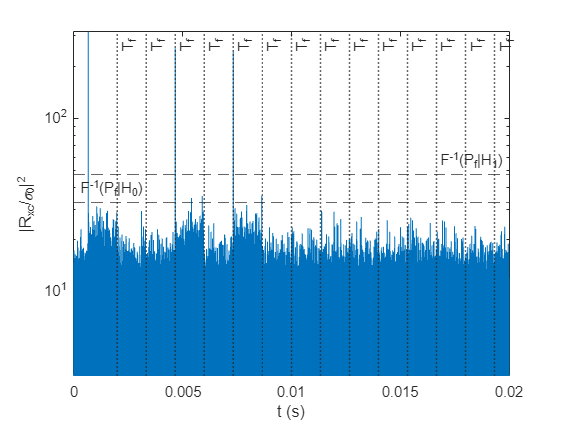

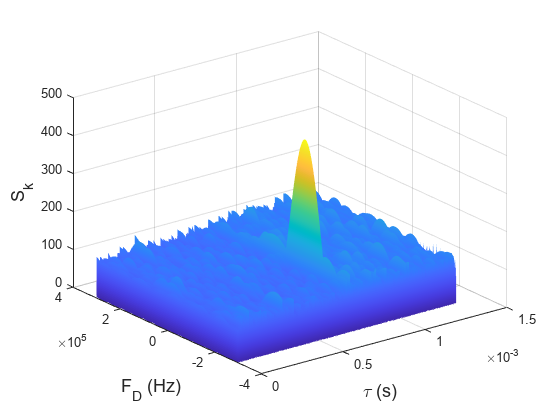

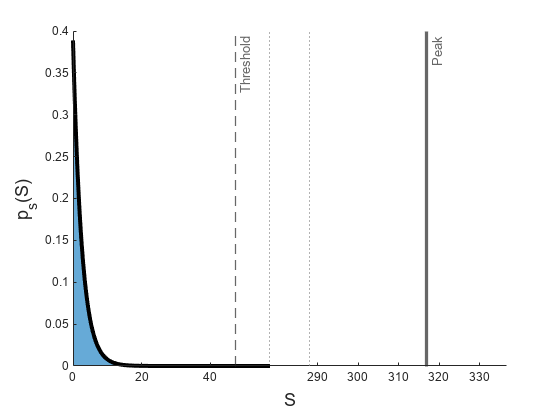


if (Fsr ~= 240e6)
    tVec = [0:length(y)-1]'/Fsr;
    [yVec,~] = resample(y,tVec,240e6,"spline");
else
    yVec = y;
end
if (getClosestFch(Fcr) - Fcr ~= 0)
    tVec = [0:length(yVec)-1]'/(240e6); 
    Fshift =  getClosestFch(Fcr) - Fcr;
    yVec = yVec.*exp(-j*2*pi*Fshift*tVec);
end

    
if (perform_acq)
    % Assuming out.grif = |S(f,k)|
    % where S_k = |S(f,k)|^2 in the paper
    % Also that k dimension is 320000 long, with frame in center
    % and no frame before it.
    [vals, idxs] = max(out.grid);
    [~, t0_idx] = max(vals);
    fd_idx = idxs(t0_idx);
    Nc = out.Nc;
    sigma2_c = out.sigma2_c;
    fDop = out.fdfine;
    tVec = [0:length(yVec)-1]'/(240e6); 
    yVec = yVec.*exp(-j*2*pi*fDop*tVec);
    c = [genPss(); genSss()];
    [R_compare,lag_compare] = xcorr(yVec(1:floor(1/750*Fs)),c);
    R_compare = abs(R_compare(floor(1/750*Fs):end));
    lag_compare = lag_compare(floor(1/750*Fs):end);
    noise_mat = R_compare(1:t0_idx-1056);
    noise_vec = noise_mat(:);
    H0_floor_2 = noise_vec'*noise_vec/length(noise_vec);
    % Peak 
    Sk_peak_2 = (R_compare(t0_idx)).^2;
    Sk_no_noise_2 = Sk_peak_2-H0_floor_2;
    % The peak |Sk| ~ Rice(nu, sigma_0) so will
    % have on average a value of (Nc*A*sigma2_c)
    A = sqrt(Sk_peak_2)./(Nc.*sigma2_c);
    Ps = A^2;
    SNR_post = Sk_no_noise_2./H0_floor_2;
    SNR_hat = SNR_post./(sigma2_c.*Nc.*Fsr/Fs);
    fprintf("SNR estimate : %.2f dB\n",pow2db(SNR_hat))

    sigma2_0 = mean(noise_vec.^2)/2;
    sigma2_w = sigma2_0*2/(Nc*sigma2_c*ratio);

    sigma2_1 = sigma2_w*sigma2_c*Nc*(SNR_hat+1)/2.*ratio;
    sigma2_2 = sigma2_w*sigma2_c*Nc/2.*ratio;
    mu = Nc*sqrt(Ps)*sigma2_c.*ratio;

    H1_samples = R_compare(t0_idx+1056:end);
    H1_samples = H1_samples.^2./sigma2_0;
    
    
    threshold1 = gaminv(1-Pfcell, 1, 2*sigma2_1./sigma2_0);
    threshold0 = chi2inv(1-Pfcell,1);
    s_star = Sk_peak_2./sigma2_0;
    cuttoff = threshold1 + 10;

    % -- xcorr 
    if (crossCorr_en)
        figure(3);clf
        c = [genPss(); genSss()];
        [Rxc, lag] = xcorr(yVec,c);
        Rxc = abs(Rxc(length(yVec):end));
        Rxc = abs(Rxc).^2./sigma2_0;
        lag = lag(length(yVec):end);
        semilogy(lag./(240e6),Rxc)
        yline(threshold0,"--","F^{-1}(P_{f}|H_0)","LabelHorizontalAlignment","left")
        yline(threshold1,"--","F^{-1}(P_{f}|H_1)")
        xlabel("t (s)")
        ylabel("|R_{xc}/\sigma_0|^2")
        ylim([0.1*threshold0 max(Rxc)])
        frame_idx = t0_idx./(240e6);
        Nframes_max = floor((lag(end)-t0_idx)./(Fs./750));
        frame_loc = frame_idx + (1:Nframes_max)./750;
        if (~isempty(frame_loc))
            xline(frame_loc,':',"T_{f}","LineWidth",1)
        end
    end

    if aqPlot_en
        [X,Y] = meshgrid(out.tauvec,out.fdvec);
        figure(4);clf
        surf(X,Y,out.grid(:,:),'linestyle','none','FaceColor','interp','EdgeColor','none','FaceLighting','gouraud')
        xlabel('\tau (s)','FontSize', fontsize)
        ylabel('F_D (Hz)','FontSize', fontsize)
        zlabel("S_{k}",'FontSize', fontsize)
    end

    if hist_en
        s = linspace(0,cuttoff,1000);
        H1 = gampdf(s, 1, 2*sigma2_1./sigma2_0);
        figure(5); clf;
        if (s_star > cuttoff+30)
            t = tiledlayout(1,2,'TileSpacing','compact');
            bgAx = axes(t,'XTick',[],'YTick',[],'Box','off');
            bgAx.Layout.TileSpan = [1 2];
            ax1 = axes(t);
            histogram(ax1,H1_samples,'EdgeColor','none','Normalization','pdf')
            hold on;
            plot(s,H1,'LineWidth',3,'Color','black')
            hold off;

            xline(threshold1,"--","Threshold","Linewidth",1)
            xline(ax1,cuttoff,':');
            ax1.Box = 'off';
            xlim(ax1,[0 cuttoff])

            ax2 = axes(t);
            ax2.Layout.Tile = 2;
            xline(ax2,s_star-29,':');
            xline(ax2,s_star,'-',"Peak",'LineWidth',2.5);
            xlim([s_star-29 s_star+20])
            ax2.YAxis.Visible = 'off';
            ax2.Box = 'off';

            xlabel(t,"S",'FontSize',fontsize)
            ylabel(t,"p_s(S)",'FontSize',fontsize)
        else
            histogram(H1_samples,'EdgeColor','none','Normalization','pdf')
            xlim([0 max(s_star,threshold1) + 10])
            hold on;
            plot(s,H1,'LineWidth',3)
            xline(s_star,'-',"Peak",'LineWidth',2.5);
            xline(threshold1,"--","Threshold","Linewidth",1)
            hold off;
            xlabel("S",'FontSize',fontsize)
            ylabel("p_s(S)",'FontSize',fontsize)
        end
    end
end